# Solving Blackjack with Q-Learning

## Overview

This example illustrates using reinforcement learning (RL), specifically Q-Learning, to learn a policy to play the casino card game blackjack.  The purpose of the example is to provide **minimal working example** to illustrate the implementation of a Q-learning strategy.

The MATLAB implementation is intentionally procedural and specific, limiting the use of objects and avoiding the Mathworks RL toolbox, to allow folks new to RL to experiment efficiently without the need to learn specific frameworks.

### Attribution

Adapted from the Farama Foundation's Gymnasium tutoral, [Solving Blackjack with Q-Learning](https://gymnasium.farama.org/tutorials/training_agents/blackjack_tutorial/): 

- The custom blackjack environmet is based on the Gymnasium [blackjack.py](https://github.com/Farama-Foundation/Gymnasium/blob/main/gymnasium/envs/toy_text/blackjack.py) environment, but is implementd as a standalone MATLAB class.

## Blackjack Environment

To formulate the problem appropriate for an RL approach the agent interacts with the game through the following interface:

- **Action Space** (Scalar, discrete values): stand (1) or hit (2).

- **Observation Space **(Vector of length 3, discrete):   `[player_sum, dealer_card, usable_ace]`   Where `player_sum` is the current total value of the player's hand from 4-21; `dealer_card` is the dealer's showing card value from 1-10; and usable ace describes whether the player holds a usable ace, 0-false or 1-true.

- **Rewards**: +1 for win, -1 for lose, 0 for draw, +1.5 for natural blackjack.

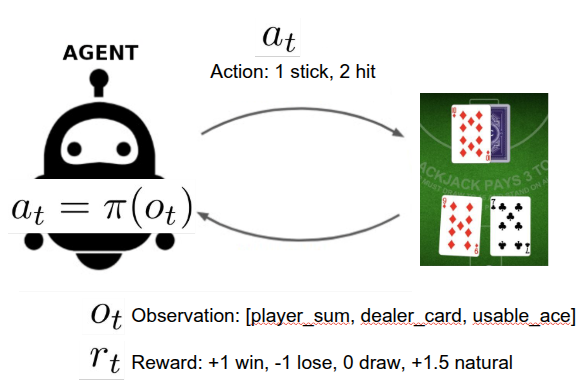

(The MATLAB implementation is adapted from the Gymnasium [blackjack environment](https://gymnasium.farama.org/environments/toy_text/blackjack/).  Note that in this implementation the action space is 1, 2 to deal with MATLAB's array indexing.)

## Setup environment

Make sure that the file **BlackJackEnv.m** is in MATLAB's path or the current working directory and instatiate the environment **object**.

The two input arguments are optional.   The `natural` variable is a logical (true/false or 1/0).   If true, three an additional reward (+1.5) starting with a natural blackjack, i.e. starting with an ace and ten (sum is 21).   If false, a natural blackjack receives an award of 1.0.   The `seed` argument allows the user to supply an argument to control  the random number generator, see MATLAB's [`rng`](https://www.mathworks.com/help/matlab/ref/rng.html) function.

So we can create a new game environment with 

env = BlackJackEnv(1)

env =   BlackJackEnv with properties:

      action_size: 1
    current_state: []
        max_steps: 10
       step_count: 0
             deck: [1 2 3 4 5 6 7 8 9 10 10 10 10]
           dealer: []
           player: []
          natural: 1

### Methods:

The two main method of the environment are

- `reset()` which starts a new game and provides an initial observation of the state of the game.

- `step(action)` which takes an action and returns the next state of the game, where action can be `1` for stand and `2` for hit.

## `reset:` Starting a game and observing the environment

Get the initial state (observation) of a new game.  Recall that the observation is   `[player_sum, dealer_card, usable_ace]`  .

[initial_obs, info] = env.reset()

initial_obs =     17     8     0


info = struct with fields:
    episode_step: 0

## `step:` Executing an action

Random action within action space of {1, 2}.  `1` for stand and `2` for hit.

Let's take a card, i.e., hit and exectute the action to see the results.

action = 2;
[next_obs, reward, terminated, truncated, info] = env.step(action)

next_obs =     23     8     0


reward = -1

terminated = logical
   1

truncated = logical
   0

info = struct with fields:
    episode_step: 1
     dealer_hand: [8 10]

Stand.  

Did we win or lose?

action = 1;
[next_obs, reward, terminated, truncated, info] = env.step(action)

next_obs =     23     8     0


reward = -1

terminated = logical
   1

truncated = logical
   0

info = struct with fields:
    episode_step: 2
     dealer_hand: [8 10]

## Create a Q-Table

A fundamental concept of the Q-learning approach is to estimate the true **value** of each state-action pair.  This mapping (lookup table) from state (observations) to actions in represented as a **Q-table** of state-action pairs: $Q(S,A)$.

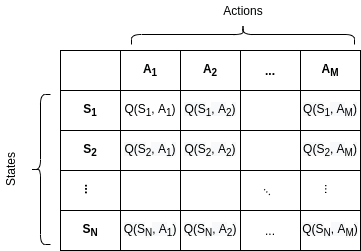

This representation is key to understanding the approach of the algorithm.   If the true optimal value table is known, $Q^*(S,A)$, the optimal policy would be to simply select the action that yields the maximum value for the current state, i.e.,

$\pi^*(S) = A  = \arg\max_{A} Q^*(S, A)
$.

This equation means: choose the action aaa that gives the highest Q-value.

However, our agent needs to **explore** the environment to be able to estimate this value function which simultaneously **exploiting** the current estimate to make decisions with an uncertain estimate.

A [dictionary ](https://www.mathworks.com/help/matlab/ref/dictionary.html)data structure is convenient way to represent this Q-table:

- The dictionary **key** for each element an array current state/observation: `[sum of players hand, dealer's face card, usable ace]`

- The corresponding dictionary **value** for each element is a 2x1 array of the current estimate of the value (current and future rewards) of each of the two possible actions (hit or stand)

function qtable = init_qtable()
    % Function to create a Q-Table with all zeros.
    qtable = dictionary();
    % Player sum
    for ps = 2:21

q =      0
     0


        % Dealer face card
        for df = 1:10
            % Usable ace
            for ua = 0:1
                observation = [ps, df, ua];
                qtable({observation}) = {zeros(2,1)};
            end
        end
    end
end

qtable = init_qtable();

Accessing a specific value in the Q-table dictionary is a two-step process

observation = [10, 1, 0];
qc = qtable({observation});
q = qc{1}

action = 1

## Adaptive Epsilon-Greedy Action Selection

We need to balance ***exploration*** (using the information we have gathered to maximize rewards) with ***exploration*** (gathering more information to imporove the policy).  Epsilon-Greedy is a simple method to balance exploration and exploitation by choosing between exploration and exploitation randomly. The epsilon-greedy, where epsilon refers to the probability of choosing to explore, exploits most of the time with a small chance of exploring.


$$A_t = \left\{ \matrix{\text{random action}   \:\:\:\: \text{with probabilty } \epsilon  \cr
\max_{A_t} Q(S_t,A)   \:\: \text{with probabilty } 1-\epsilon

}$$


A function to produce an action based on the current Q-Table, the current state of the game and the value of 

function action = get_action(qtable, observation , epsilon)
    if rand () < epsilon
        action = randi([1,2]);
    else
        qc = qtable({observation});
        [maxval, maxi] = max(qc{1});
        action = maxi;
    end

qtable =
  dictionary (cell ⟼ cell) with 400 entries:
    {[2 1 0]}   ⟼ {2×1 double}
    {[2 1 1]}   ⟼ {2×1 double}
    {[2 2 0]}   ⟼ {2×1 double}
    {[2 2 1]}   ⟼ {2×1 double}
    {[2 3 0]}   ⟼ {2×1 double}
    {[2 3 1]}   ⟼ {2×1 double}
    {[2 4 0]}   ⟼ {2×1 double}
    {[2 4 1]}   ⟼ {2×1 double}
    {[2 5 0]}   ⟼ {2×1 double}
    {[2 5 1]}   ⟼ {2×1 double}
    {[2 6 0]}   ⟼ {2×1 double}
    {[2 6 1]}   ⟼ {2×1 double}
    {[2 7 0]}   ⟼ {2×1 double}
    {[2 7 1]}   ⟼ {2×1 double}
    {[2 8 0]}   ⟼ {2×1 double}
    {[2 8 1]}   ⟼ {2×1 double}
    {[2 9 0]}   ⟼ {2×1 double}
    {[2 9 1]}   ⟼ {2×1 double}
    {[2 10 0]}  ⟼ {2×1 double}
    {[2 10 1]}  ⟼ {2×1 double}
    {[3 1 0]}   ⟼ {2×1 double}
    {[3 1 1]}   ⟼ {2×1 double}
    {[3 2 0]}   ⟼ {2×1 double}
    {[3 2 1]}   ⟼ {2×1 double}
    {[3 3 0]}   ⟼ {2×1 double}
    {[3 3 1]}   ⟼ {2×1 double}
    {[3 4 0]}   ⟼ {2×1 double}
    {

temporal_difference = 1

end

Test

observation = [10, 1, 0];
epsilon = 0.5;
action = get_action(qtable, observation, epsilon)

For this problem, we want to start with a bias towards exploration (high epsilon), but transition towards exploitation (low epsilon).  We can do this by adapting the value of epsilon as we train using a linear decay.


$$\epsilon_t = \epsilon_{\text{start}} - \frac{t}{T} (\epsilon_{\text{start}} - \epsilon_{\text{end}})$$


## Training Loop: Update Q-Table

- **Q-learning is model-free,** meaning it uses trial-and-error to explore the environment and learns the outcomes of the actions directly, without constructing an internal model.

- **It is a temporal-different (TD) algorithm, where the predictions are reevaluated after taking a step.** Even incomplete episodes generate input for a TD algorithm. Overall, we measure how the last action is different from what we estimated initially, without waiting for a final outcome.

- **Q-learning is an off-policy algorithm.** It estimates the reward for state-action pairs based on the optimal (greedy) policy, independent of the agent’s actions. 

To train the agent, we will let the agent play one episode (one complete game is called an episode) at a time and then update it’s Q-values after each episode. The agent will have to experience a lot of episodes to explore the environment sufficiently.

The key algorithm of Q-learning is how we update our estimate of the true value of each state-action pair, the Q-table.   This iteration of the value function is expressed as  


$$Q^{new}(S_{t},A_{t})\leftarrow (1-\underbrace {\alpha } _{\text{learning rate}})\cdot \underbrace {Q(S_{t},A_{t})} _{\text{current value}}+\underbrace {\alpha } _{\text{learning rate}}\cdot {\bigg (}\underbrace {\underbrace {R_{t+1}} _{\text{reward}}+\underbrace {\gamma } _{\text{discount factor}}\cdot \underbrace {\max _{a}Q(S_{t+1},a)} _{\text{estimate of optimal future value}}} _{\text{new value (temporal difference target)}}{\bigg )} $$


Our implementatuion uses a slightly different form:


$$Q^{new}(S_{t},A_{t})\leftarrow \underbrace {Q(S_{t},A_{t})} _{\text{current value}}+\underbrace {\alpha } _{\text{learning rate}}\cdot 
{\bigg (}\underbrace {\underbrace {R_{t+1}} _{\text{reward}}+\underbrace {\gamma } _{\text{discount factor}}\cdot \underbrace {\max _{a}Q(S_{t+1},a)} _{\text{estimate of optimal future value}} - \underbrace {Q(S_{t},A_{t})} _{\text{current value}} } _{\text{temporal difference}}{\bigg )} $$


- **Learning Rate (**$\alpha \in (0,1]$**):** Controls how much weight is given to new information.  Small value of $\alpha$ generate slower learning and is more stable for noisy environments.   Larger values of $\alpha$ enable faster learning, but can cause instability in stochastic or noisy environments.  Typical values are $\gamma = 0.01-0.1$ for stochastic environments such as blackjack.

- **Discount Factor (**$\gamma \in [0,1]$**):** Determines the relative importance of future rewards compared to immediate rewards.  Low values $\gamma
$ create focus on immediate rewards and greedy decisions, but can make the agent **myopic**.   High values of $\gamma
$cause the agent to delay gratification, but can make actions overly cautious.  Typical values for RL problems are $\gamma = 0.8 - 0.95.$

To implement the value-iteration, expressed above, we create a function to update the Q-table

function [qtable, temporal_difference] = update(qtable, observation, action, reward, terminated, next_observation, discount_factor, learning_rate)
    future_q_value = 0;
    if ~terminated
        qc = qtable({next_observation});
        future_q_value = max(qc{1});
    end
    qc = qtable({observation});
    qval = qc{1};
    temporal_difference = reward + discount_factor * future_q_value - qval(action);
    qvals_cell = qtable({observation});
    new_qvals = qvals_cell{1};
    new_qvals(action) = new_qvals(action) + learning_rate * temporal_difference;
    qtable({observation}) = {new_qvals};
end


Test our update function.

learning_rate = 0.01;
discount_factor = 0.95;
observation = [10, 1, 0];
action = 1;
reward = 1;
terminated = 0;
next_observation = [15, 1, 0];
[qtable, temporal_difference] = update(qtable, observation, action, reward, terminated, next_observation, discount_factor, learning_rate)

 

## Training

Now we are ready to train our Q-Learning RL model by having it explore and exploit the game environemnt.

Re-initialize Q-Table

qtable = init_qtable();

#### Specify *hyperparameters*

We specify these as a structure so that we can keep them together and it makes it eaiser to save the results.

Info: The current hyperparameters are set to quickly train a decent agent. If you want to converge to the optimal policy, try increasing the n_episodes by 10x and lower the learning_rate (e.g. to 0.001).  But, be careful, training can be computationally demanding.

hyperparams.learning_rate = 0.01;
hyperparams.discount_factor = 0.95;
hyperparams.n_episodes = 10000;
hyperparams.start_epsilon = 0.1;
hyperparams.epsilon_decay = hyperparams.start_epsilon / (hyperparams.n_episodes / 2);  % reduce the exploration over time
hyperparams.final_epsilon = 1.0;

Run N training episodes

% Allocate storage 
rewards = zeros(1, hyperparams.n_episodes);
training_error = zeros(1, hyperparams.n_episodes);
episode_length = zeros(1, hyperparams.n_episodes);

% Starting greediness value
epsilon = hyperparams.start_epsilon;

for ii = 1:hyperparams.n_episodes
    [obs, info] = env.reset();
    terminated = false;
    % Play one episode
    while ~terminated
        action = get_action(qtable, obs , epsilon);
        [next_obs, reward, terminated, truncated, info] = env.step(action);
        % Update the agent / q-table
        [qtable, temporal_difference] = update(qtable, obs, action, reward, terminated, next_obs, hyperparams.discount_factor, hyperparams.learning_rate);

        % Update the current obs
        obs = next_obs;
    end
    rewards(ii) = reward;
    training_error(ii) = temporal_difference;
    episode_length(ii) = info.episode_step;

    % Epsilon decay
    epsilon = max(hyperparams.final_epsilon, epsilon - hyperparams.epsilon_decay);
end

## Visualize the training

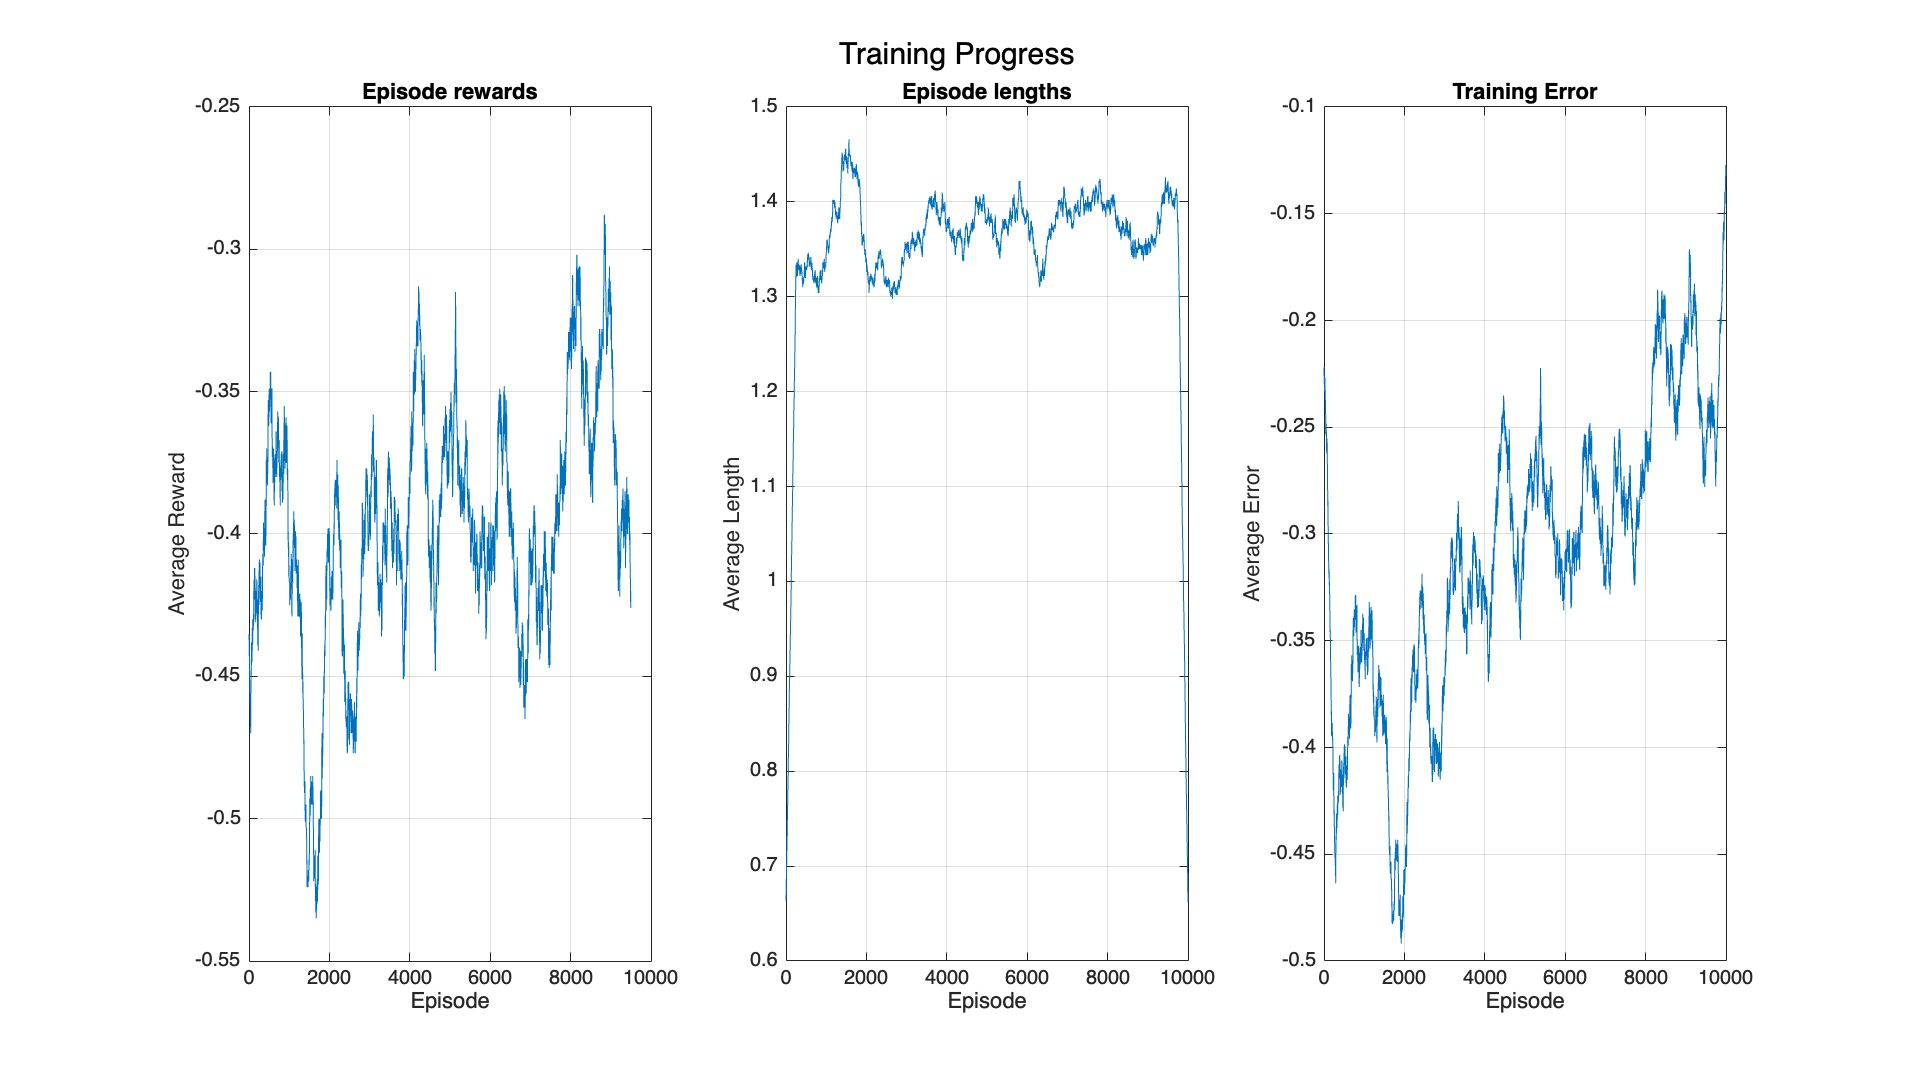

figure;
clf;

% Episode rewards plot
rolling_length = 500;
subplot(1, 3, 1);
reward_moving_average = conv(rewards, ones(rolling_length,1), 'valid') / rolling_length;
plot(1:length(reward_moving_average), reward_moving_average);
title('Episode rewards');
xlabel('Episode');
ylabel('Average Reward');
grid on;
% Episode lengths plot
subplot(1, 3, 2);
length_data = episode_length;
length_moving_average = conv(length_data, ones(rolling_length,1), 'same') / rolling_length;
plot(1:length(length_moving_average), length_moving_average);
title('Episode lengths');
xlabel('Episode');
ylabel('Average Length');
grid on;

% Training error plot
subplot(1, 3, 3);
error_data = training_error;
training_error_moving_average = conv(error_data, ones(rolling_length,1), 'same') / rolling_length;
plot(1:length(training_error_moving_average), training_error_moving_average);
title('Training Error');
xlabel('Episode');
ylabel('Average Error');
grid on;

% Adjust layout
sgtitle('Training Progress');  % Optional overall title
set(gcf, 'Color', 'white');  % White background

% Adjust spacing between subplots
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);
set(findall(gcf, 'Type', 'Axes'), 'FontSize', 10);

## Visualize the policy

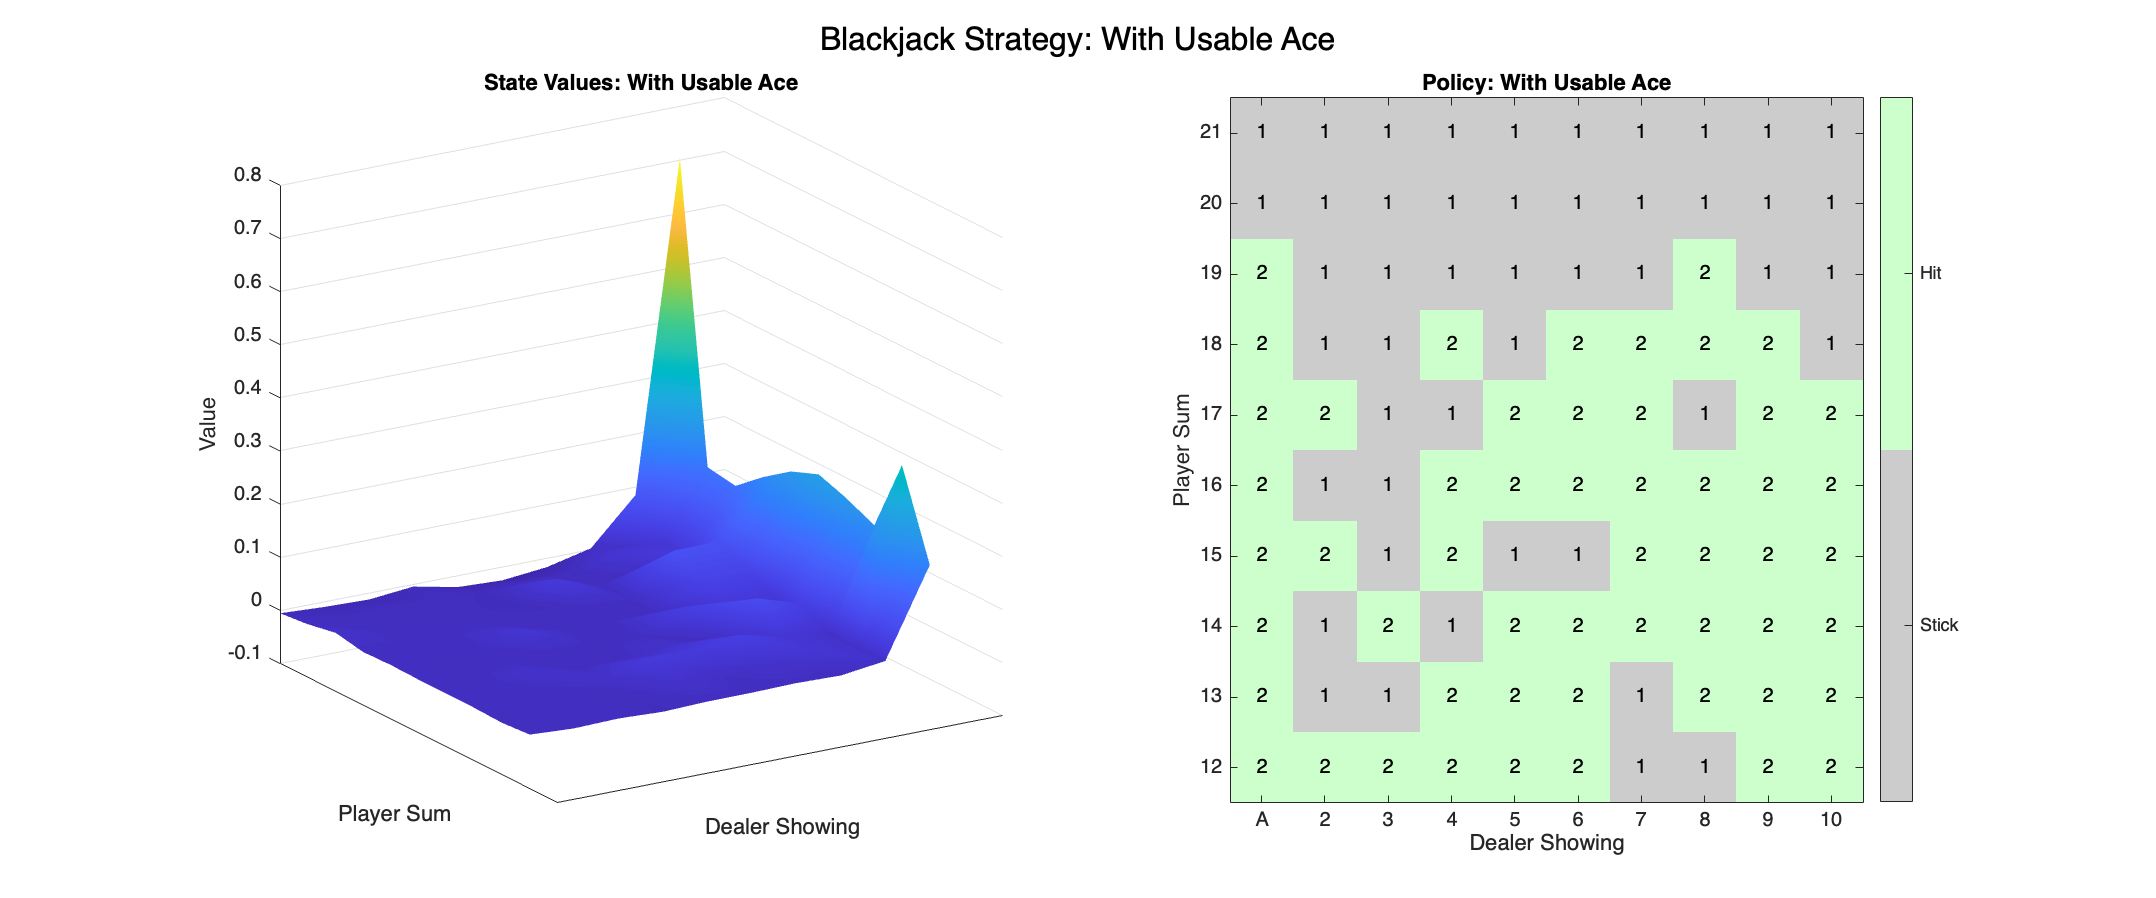

function [value_grid, policy_grid] = create_blackjack_plots(qtable, usable_ace)

    % Create value and policy grids and plot them

    
    % The minimum player sum to display depends on the usable ace.  For
    % having a usable ace, the minimum player sum is 12, 11 otherwise.
    ps_min = 11;
    if usable_ace
        ps_min = 12;
    end
    % Create meshgrid for player and dealer counts
    [dealer_count, player_count] = meshgrid(1:10, ps_min:21);
    
    % Initialize value and policy grids
    value = zeros(size(player_count));
    policy = zeros(size(player_count));
    
    % Fill in the grids
    for i = 1:size(player_count, 1)
        for j = 1:size(player_count, 2)
            state = [player_count(i,j), dealer_count(i,j), usable_ace];
            q_values = qtable({state});
            [max_value, max_action] = max(q_values{1});
            value(i,j) = max_value;
            policy(i,j) = max_action;
        end
    end
    
    % Create figure with subplots
    figure('Position', [100 100 1200 500]);
    
    % Plot state values (3D surface)
    subplot(1, 2, 1);
    surf(player_count, dealer_count, value);
    colormap(gca);
    shading interp;
    
    % Adjust 3D view
    view(-32, 19);
    
    % Labels and title
    if usable_ace
        title_text = 'With Usable Ace';
    else
        title_text = 'Without Usable Ace';
    end
    title(['State Values: ' title_text]);
    ylabel('Player Sum');
    xlabel('Dealer Showing');
    zlabel('Value');
    
    % Adjust axes
    yticks(ps_min:21);
    xticks(1:10);
    xticklabels({'A', '2', '3', '4', '5', '6', '7', '8', '9', '10'});
    
    % Plot policy (heatmap)
    subplot(1, 2, 2);
    imagesc(1:10, ps_min:21, policy);
    set(gca, 'YDir', 'normal');
    colormap(gca, [0.8 0.8 0.8; 0.8 1 0.8]); % Light green for hit, grey for stick
    
    % Add grid to policy plot
    % grid on;
    % set(gca, 'GridAlpha', 0.3, 'Layer', 'top');
    
    % Labels and title
    title(['Policy: ' title_text]);
    ylabel('Player Sum');
    xlabel('Dealer Showing');
    
    % Adjust axes
    xticks(1:10);
    xticklabels({'A', '2', '3', '4', '5', '6', '7', '8', '9', '10'});
    yticks(ps_min:21);
    
    % Add colorbar with custom labels
    c = colorbar;
    c.Ticks = [1.25 1.75];
    c.TickLabels = {'Stick', 'Hit'};
    
    % Add value annotations to policy plot
    hold on;
    for i = 1:size(policy, 2)
        for j = 1:size(policy, 1)
            text(i, j+(ps_min-1), num2str(policy(j, i)), ...
                'HorizontalAlignment', 'center', ...
                'Color', 'black');
        end
    end
    hold off;
    
    % Adjust overall figure appearance
    sgtitle(['Blackjack Strategy: ' title_text], 'FontSize', 16);
    set(gcf, 'Color', 'white');
    
    % Return grids if needed
    value_grid = {player_count, dealer_count, value};
    policy_grid = policy;
end

[value_grid, policy_grid] = create_blackjack_plots(qtable, 1);
[value_grid, policy_grid] = create_blackjack_plots(qtable, 0);

**Compare to GroundTruth:**

In teaching Q-learning using blackjack, we often compare Q-learning results to those from Monte Carlo Exploring Starts (MC-ES), because Q-learning is a more general and flexible method applicable to a wide range of environments, while MC-ES is a specific algorithm that, under its assumptions, provides provably optimal results in small, discrete, episodic environments.

## 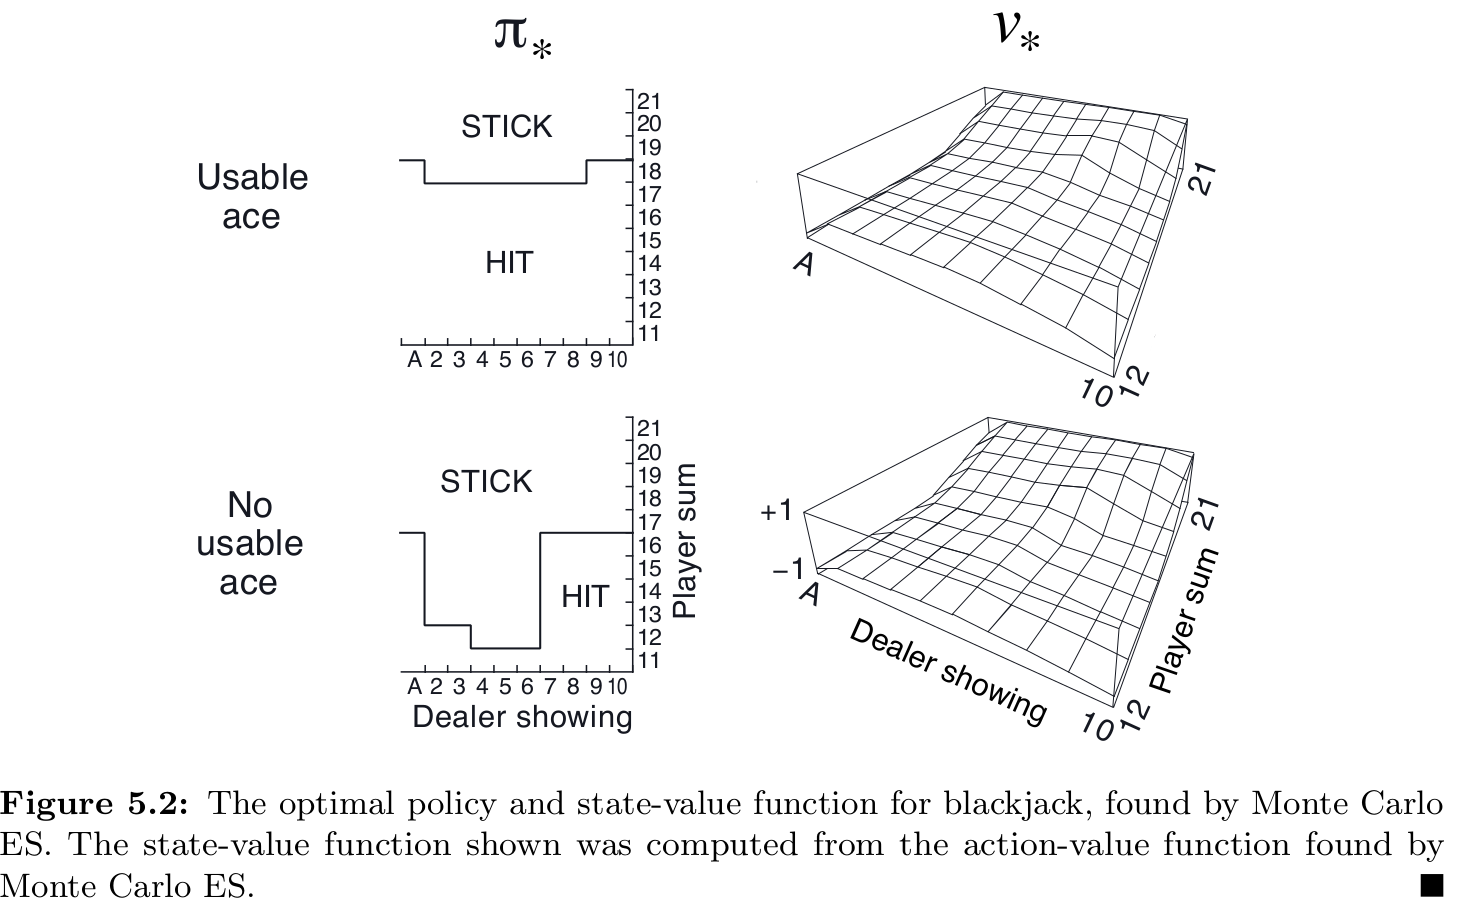

## Save the results

Because it can take significant compute to do the training, we want to save the results as a .mat file for later

%save("blackjack_qlearning.mat", "qtable", "hyperparams")